clear; close all; clc;

# **MATLAB-What is the Data Saying-Statistics Workshop-29.05.18 **

Created by Doruk Usluel & Alicia Takbash

Facebook: MATLAB @ Unimelb

Twitter: @Alicia_Tak

Email: alicia.resplat@gmail.com

Based on the Introduction to Statistical Methods with MATLAB Course

# Introduction

With the amount of data involved in any process increasing rapidly it has never been so vital to anlyze large amounts inputs in structured and automated methods to obtain menaingful outcomes and draw conclusions.

This workshop focuses  on fundementals of applying statistical methods in MATLAB. Useful tools and excersizes are shown through example datasets and are results are visualised in various types. The aim is to familiarize the MATLAB user to applying statistical applications with the use of common MATLAB functions. This workshop also provides practice for creating your own simulated datasets and the use of creating different types of random numbers.

# 1. Statistics and Distributions

## 1.1 Visualizing Data

Several common useful data visualization  techniques useful in statistical analysis and very simple to implement in MATLAB are:

- Histograms: A histogram gives important insight about how a data is distributed, making it easy to answer questions such as: What are the most frequent values in the data? What is the range of the values in the data? Is there an order to the distribution of the values?

MATLAB function: histogram

- Box Plots: Being one of the most common visualisation techniques, box plots clearly and neatly show aspects of the dataset by outlining the boundries of the data set; collecting significant chunks of the data into identifiable groups; point out outliers and more!

MATLAB function: boxplot

- Scatter Plots: As another famous visualisation technique, scatter plots allow to understand the relationships between different variables with very little work. It is one of the fastests way to explore or demonstrate if two different variables have a common affect on the aspect of interest or if they do, they make it clear and easy to understand.

MATLAB function: scatter, scatter3

Lets start by creating our own dataset:

% Creating a data set of [First Letter, Height, Age, Do you like coffee, number of pets]
% Alphabet
alph = 'A':'Z';
cd = ["Cat" "Dog"];
first_letter = [];
for i=1:1000
    first_letter = [first_letter;alph(randi(numel(alph)))]; % english alphabet
    height(i) = (130+normrnd(0.5,0.5)*(220-130)); % between 130cm and 220cm
    age(i) = (13+rand*((i/10)+30-13)); % between 13 and 130
    coffee_yn(i) = randi([false true]); % 0 (no) 1 (yes)
    pet_num(i) = rand*(i/10); % 0 to 100 pets
end
RandomData.FL = first_letter;
RandomData.H = height;
RandomData.A = age;
RandomData.Cyn = coffee_yn;
RandomData.PN = pet_num;

Now we have a dataset we should start to explore the data distribution and characteristics using visualizations.

**Histogram**

Lets see what the histogram of the heights shows:

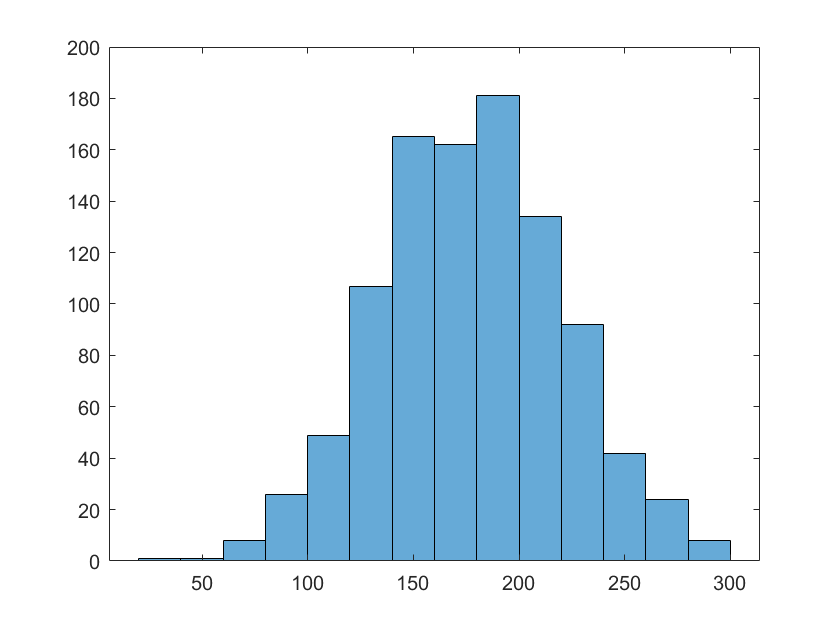

histogram(RandomData.H)

Now another one for age

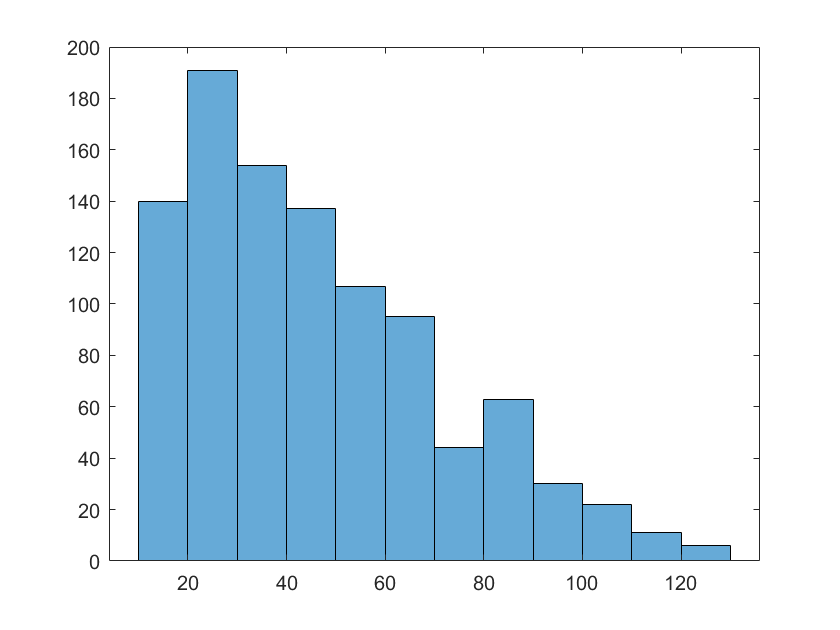

histogram(RandomData.A)

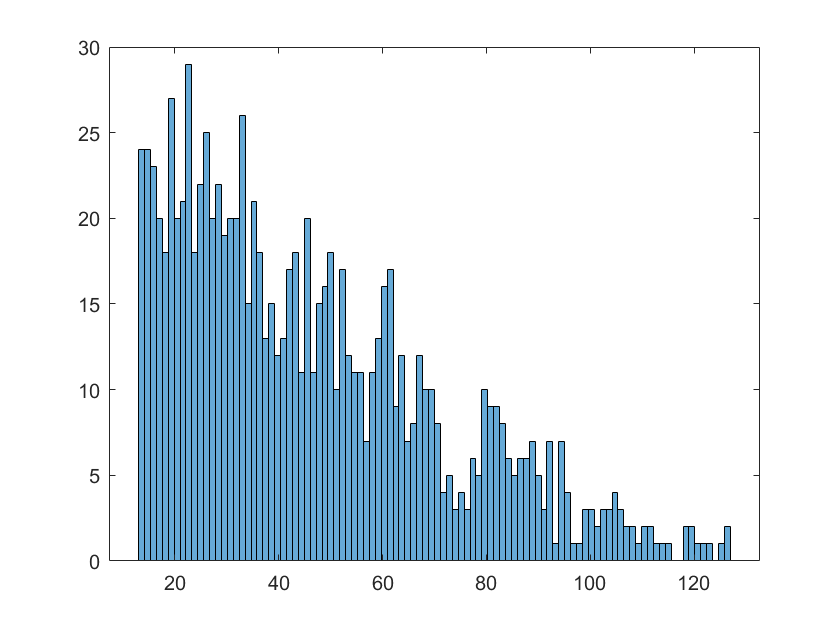

% you can select the number of bins you want in your histogram
histogram(RandomData.A,100)

Now try to create a histogram for the first letters. What needs to be added

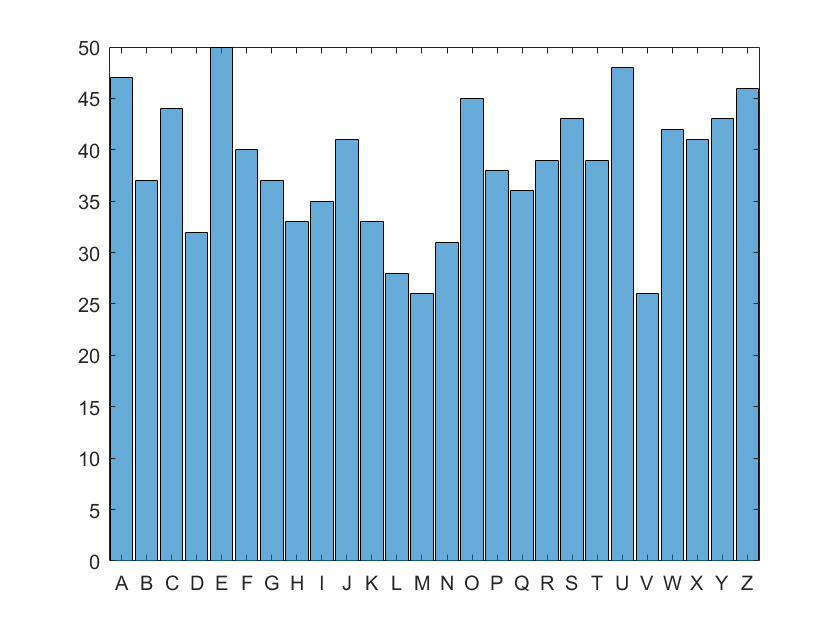

histogram(categorical(cellstr(RandomData.FL))) % for non numeric values...

% the categories need to be converted to categorical array in order to be evaluated numerically
% Now play with the bin numbers

[https://au.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html](https://au.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)

**Scatter**

Let's discover if there is any relationship between the age and number of pets a person owns.

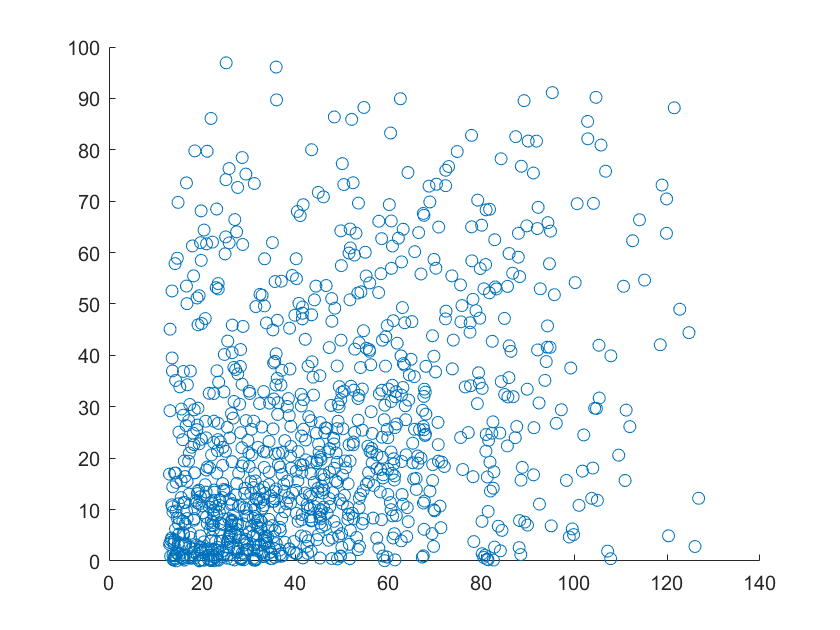

scatter(RandomData.A,RandomData.PN)

What about 1st letter of name and if they like coffee

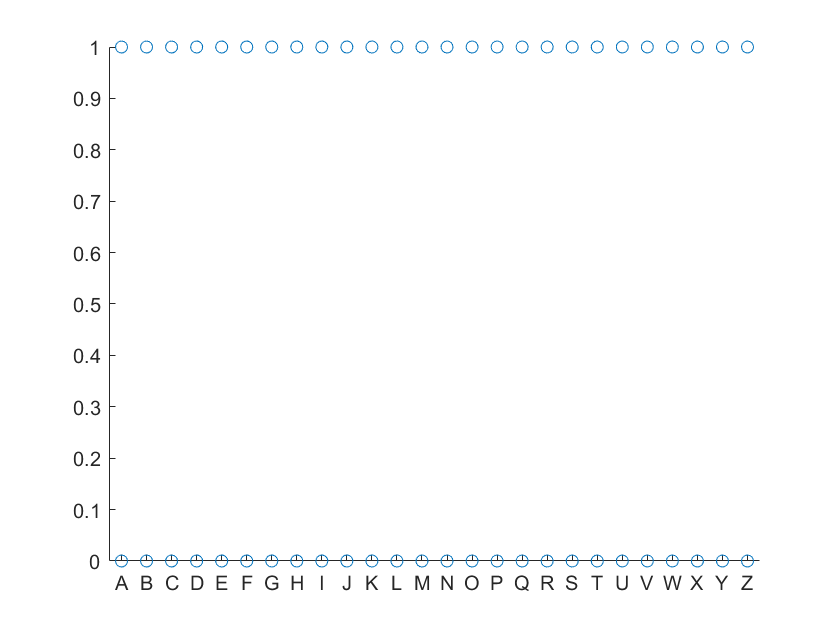

scatter(categorical(cellstr(RandomData.FL)), RandomData.Cyn)

**Box Plots**

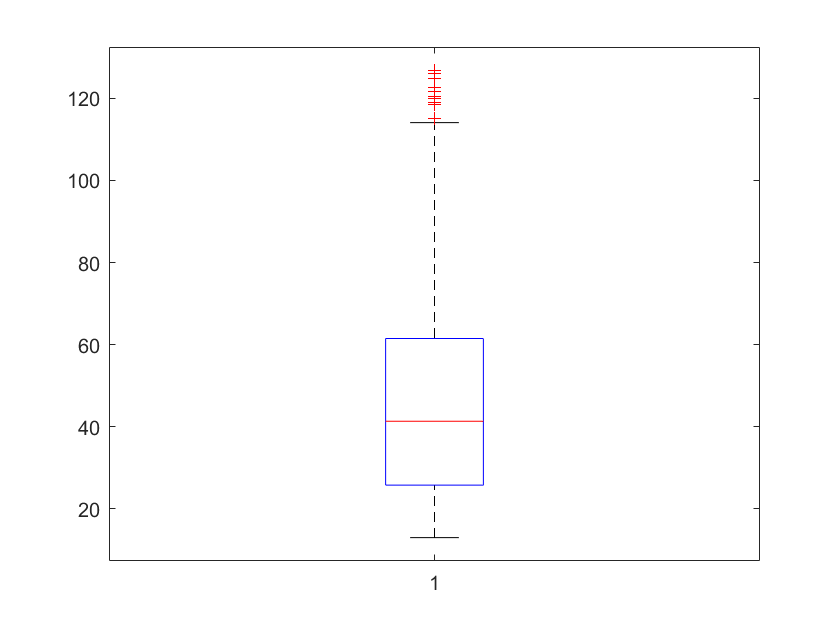

% observe box plot of the ages
boxplot(RandomData.A)

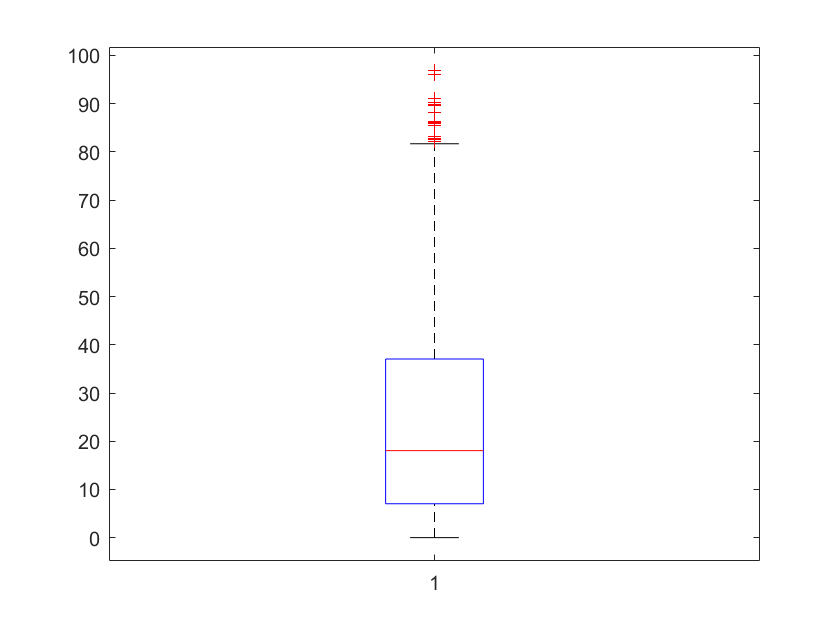

% try the number of pets
boxplot(RandomData.PN)

Challenge: Create another dataset and plot two seperate age group histograms on top of each other using hold on.

                    Using the same second dataset to plot two boxplots

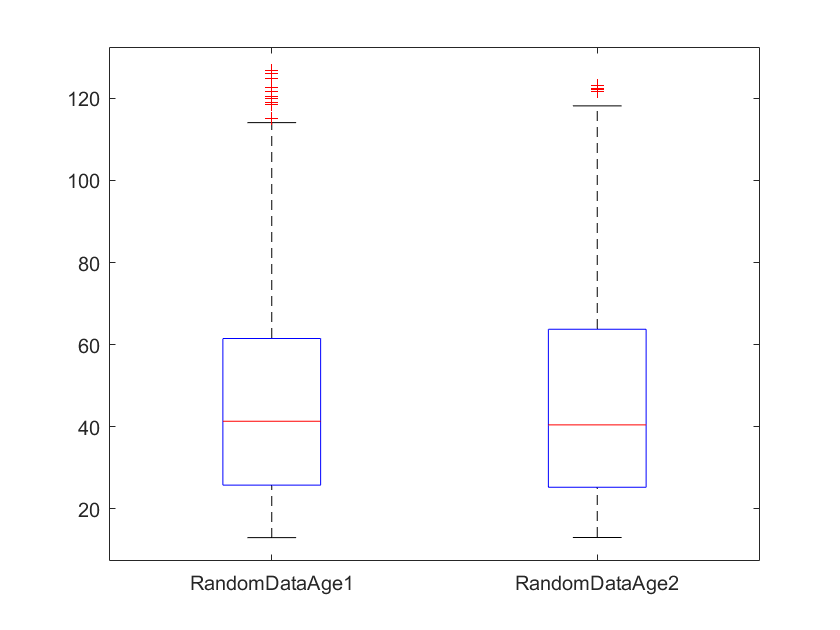

first_letter = [];
for i=1:1000
    first_letter = [first_letter;alph(randi(numel(alph)))]; % english alphabet
    height(i) = (130+normrnd(0.5,0.5)*(220-130)); % between 130cm and 220cm
    age(i) = (13+rand*((i/10)+30-13)); % between 13 and 130
    coffee_yn(i) = randi([false true]); % 0 (no) 1 (yes)
    pet_num(i) = rand*(i/10); % 0 to 100 pets
end
RandomData2.FL = first_letter;
RandomData2.H = height;
RandomData2.A = age;
RandomData2.Cyn = coffee_yn;
RandomData2.PN = pet_num;
% set groups
groups = [ones(size(RandomData.A))';
    2*ones(size(RandomData2.A))'];
% plot two box plots
boxplot([RandomData.A'; RandomData2.A'],groups')
set(gca,'XTickLabel',{'RandomDataAge1' 'RandomDataAge2'})

## 1.2 Centrality and Spread

For distributions of data certain parameters determine what is average or common. For example variables can differ according to many factors such as demographical, economical, physiological and many other factors depending on the context. Because of these certain parameters determining centrality of a certain group of data should be considered in an analysis. Such as the:

- Mean

- Median

- Mode

- also trimmean in MATLAB is the mean excluding outliers

Create two sets of populations with 1000 people each for different age groups, and assign to them a normal distribution of blood pressure.

% Create age groups
AgeGroup_young = normrnd(15,3,1000,1);
AgeGroup_adult = normrnd(50,3,1000,1);

% Now create the blood pressure data
BPres_young =  normrnd(60,10,1000,1);
BPres_adult =  normrnd(70,10,1000,1);


Plot histogram of ages for different age groups.

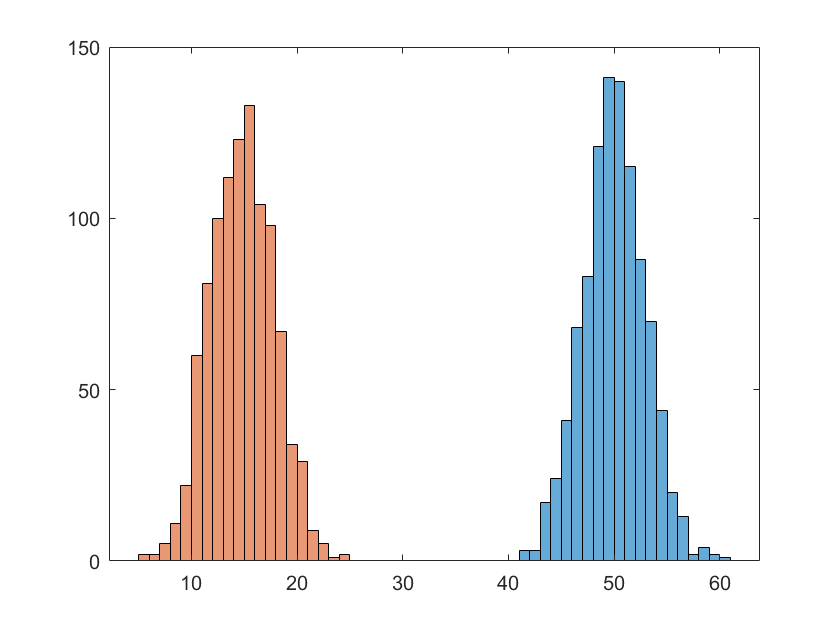

% Visualize the age histograms
figure
histogram(AgeGroup_adult);hold on
histogram(AgeGroup_young);hold off

Plot histogram of blood pressures for different age groups.

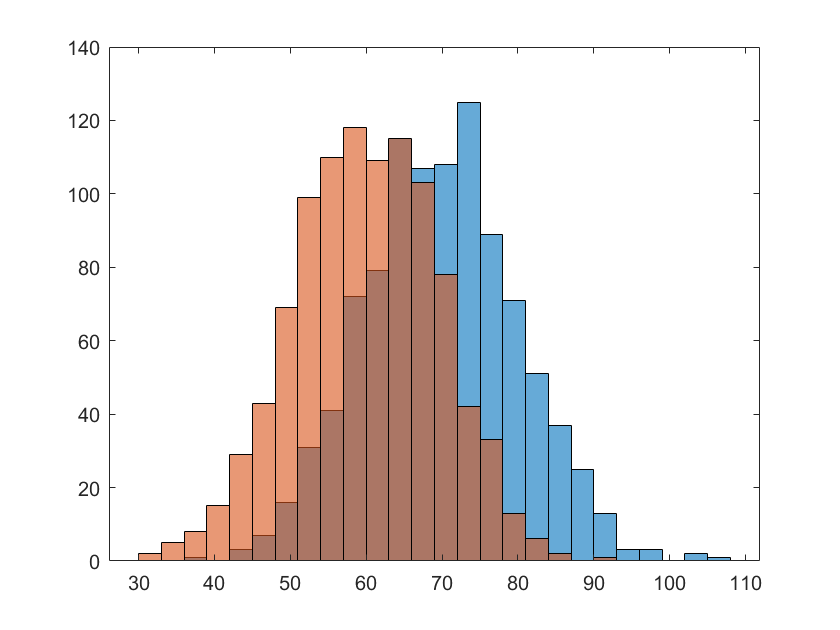

% Visualize the blood pressure histograms
figure
histogram(BPres_adult);hold on
histogram(BPres_young)

Calculate and plot the mean blood pressures for the two different age groups.

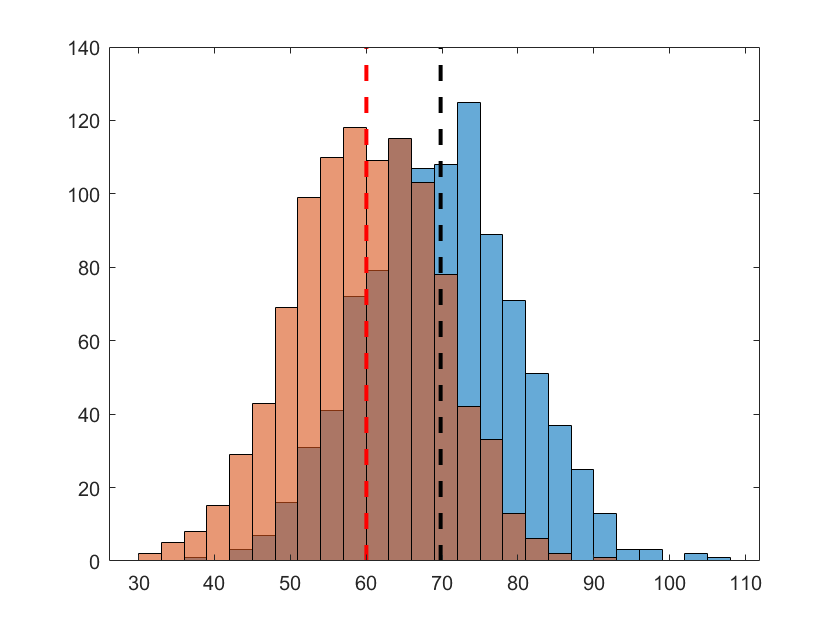

mBP_young = mean(BPres_young);
line([mBP_young mBP_young],get(gca,'YLim'),'LineWidth',2,'Color','r','LineStyle','--')
mBP_adult = mean(BPres_adult);
line([mBP_adult mBP_adult],get(gca,'YLim'),'LineWidth',2,'Color','k','LineStyle','--')

Observe the difference between mean and median and mode values.

Plot box plots in the same figure side by side to observe the outliers of each age group.

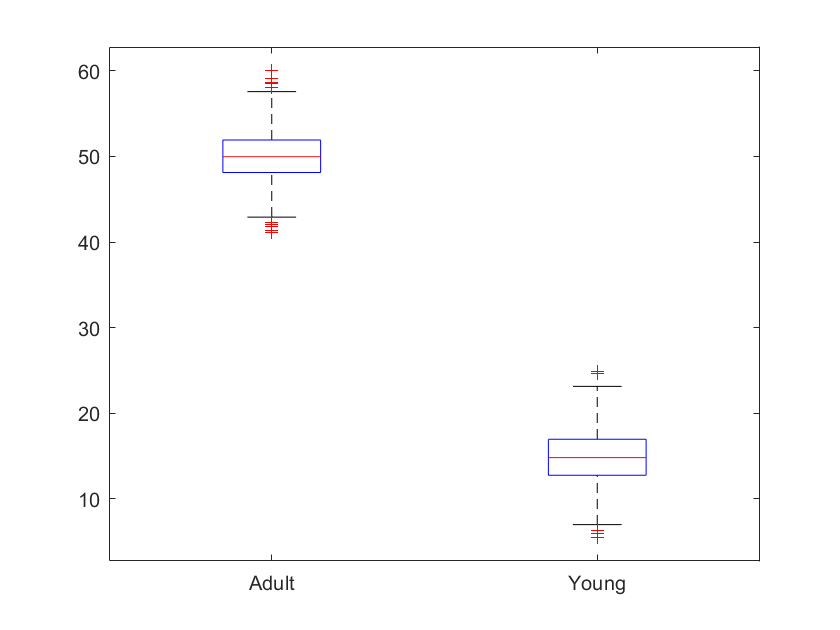

% set groups
groups = [ones(size(AgeGroup_adult));
    2*ones(size(AgeGroup_young))];
% plot two box plots
boxplot([AgeGroup_adult; AgeGroup_young],groups)
set(gca,'XTickLabel',{'Adult' 'Young'});hold off

The above centrality values do not express the distribution of data accurately:

- Standard deviation: Is an important aspect of data distribution as centrality values alone do not give enough information to understand the distribution of data in a group. It shows the tendency of the data to deviate from the central values.

MATLAB function: std

- Interquantile range: Gives the distance between the data that contains 50% of the distribution, between the 25% and 75% of the data.

MATLAB function: iqr

Additional spread values:

- range: distance between max and min values

- var: variance of a data set (square of the standard deviation)

Calculate the standard deviation and interquantile range of the blood pressures for the different age groups.

stdBPyoung = std(BPres_young);

## 1.3 Different Distributions

The distribution of a data can provide insight about the probability of getting a certain values in the dataset. This can be defined as the probability density function. The histogram is a quantitavie approximation of this value as it provides a frequency of any given value of data in a sampled set.

By using the normalize function of the histogram (name-value pair), the counts of the histogram can be converted to an approximation of probability density functions.

Find the probability distribution for the blood pressures of an individual in the young age group:

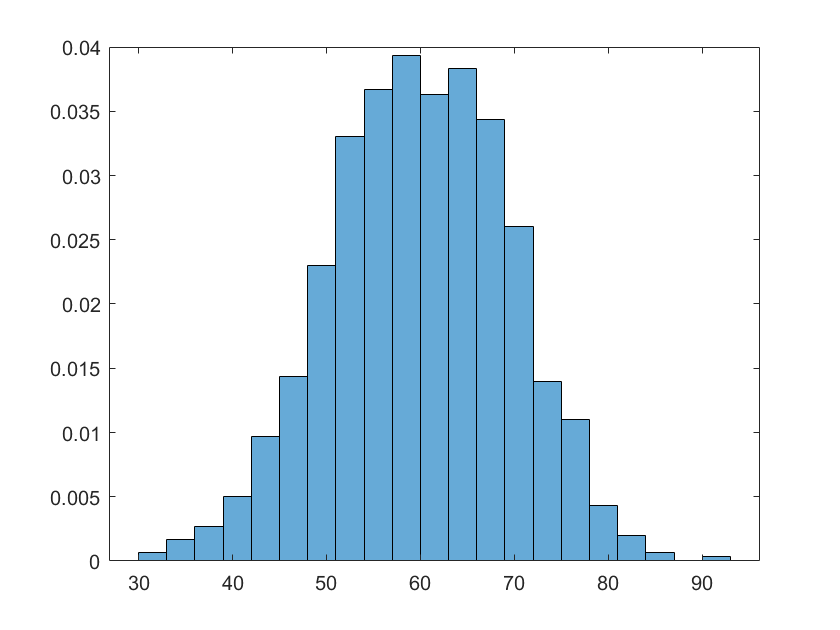

% plot the normalized histogram
figure
histogram(BPres_young,'Normalization','pdf')

Some very common distributions are:

- uniform distribution: a distribution with equal probabilities on the given range

- normal distribution: a "bell shaped" distribution with a mean of 0 and a standard deviation 1

**Creating a distribution**

You have obtained the mean and standard deviation of the blood pressures in the previous example. And you want to learn what is the probability of certain blood pressures being present in this distribution. The normpdf function can calculate the probability of having an example set of blood pressures in the same probability assuming a normal distribution in the set.

Calculate the probabilities for a certain set of blood pressures and plot probabilities on the sample blood pressure set:

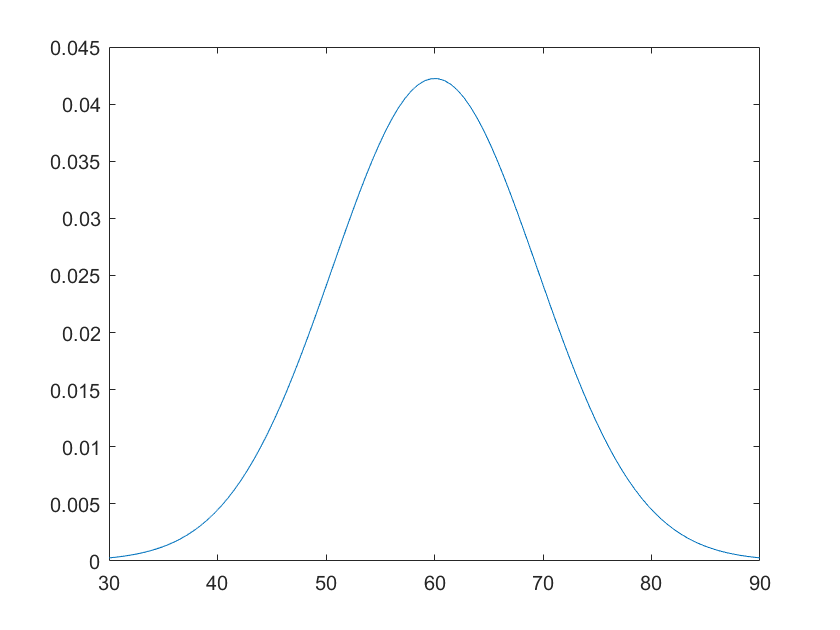

% obtain a set of sample blood pressure values
BPs = linspace(30,90,100);
% use normpdf to calculate the probabilites of having the given blood pressure values
pdfBPyoung = normpdf(BPs,mBP_young,stdBPyoung);
% plot the probabilities against the sample blood pressures
figure
plot(BPs,pdfBPyoung)

However this pdf will not give the exact distribution of the sample set and will be an approximation.

Hold the pdf plot and plot the sampled histogram data, by using the normalization option:

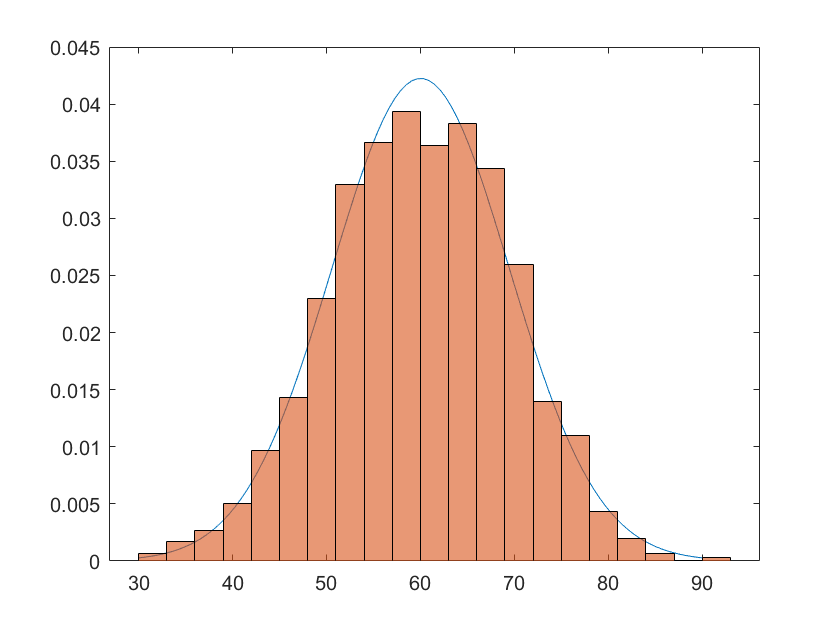

hold on
histogram(BPres_young,'Normalization','pdf')
hold off

**Random Numbers with Specific Distributions**

As we have seen it is possible to generate random numbers in MATLAB (well pseudo-random...). However it is also possible to generate random numbers that are selected from a specific distribution as well. So it is possible to simulate data with estimated distributions which then can be compared to actual observations.

- rand: uniformly distributed random numbers

- randn: normally distributed random numbers

# 2. Fitting Curves

## 2.1 Linear Regression

Assume that after using the scatter plot you have observed that there was a correlation between two parameters.

Creat two variables containing random numbers with uniform distributions, but both variables should be increasing.

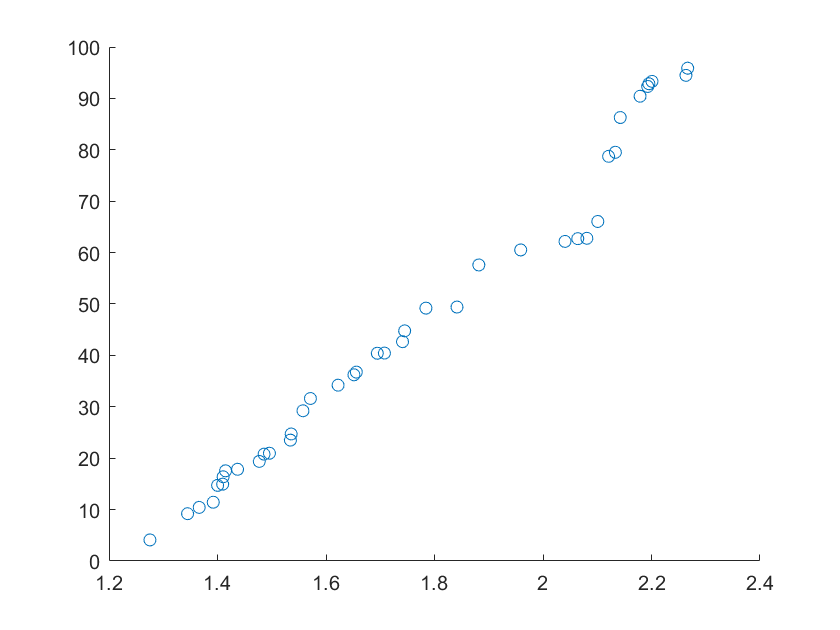

% Variables are amount of chocalate placed in crepes and the amount sold
choc_amount = sort(rand(40,1)+rand*5);
crepes_sold = sort(100*rand(40,1)+rand*10);
% plot the behaiour betweenthe parameters
scatter(choc_amount,crepes_sold)

Now you want to find the trend between these two variables as a mathematical function. SImply put you want to place a line of best fit on your data to observe the trend. This is a very simple application of linear regression.

The fit function can be used to simply fit a line through the two variables, which in turn will give you the parameters of the line of best fit.

Fit a line to your data:

% tip the fit function requires both sets of data to be inputted as column vectors
chocsellfit = fit(choc_amount,crepes_sold,'poly1')

chocsellfit =      Linear model Poly1:
     chocsellfit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       90.62  (85.9, 95.35)
       p2 =      -113.5  (-122, -105.1)

% For those who might not have the fit function can use the polyfit function
chocsellfit2 = polyfit(choc_amount,crepes_sold,1)

chocsellfit2 =    90.6240 -113.5236


Challenge: create a quadratic dataset with radom errors on each point. Then fit a second order polynomial to the dataset. Plot the resulting fit and the data.

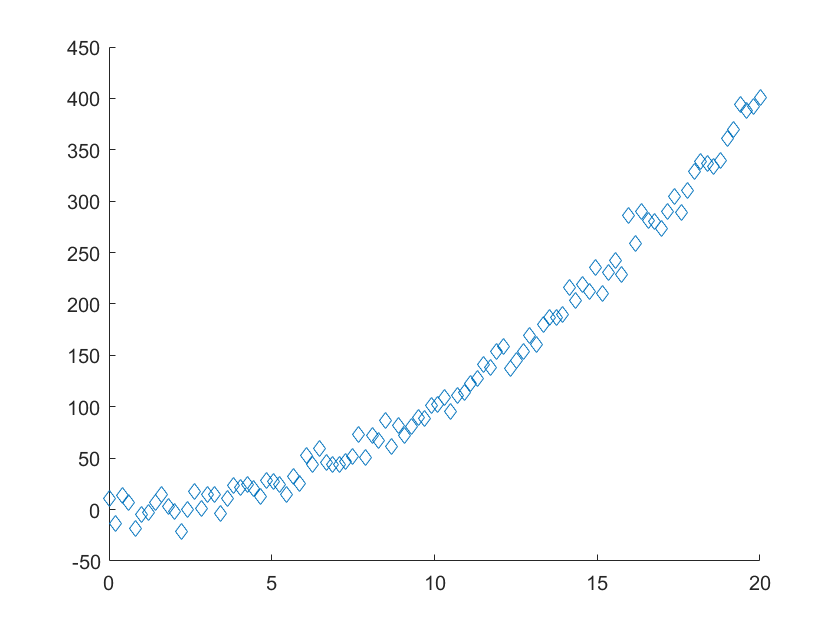

% x-variables
x = linspace(0,20);
%random errors
err = 10*randn(1,100);
% y-varibles
y = x.^2;
% add the random errors
y = y+err;
% plot the behaviour
scatter(x,y,'Marker','diamond')

% fit a quadratic polynomial
quadfit = fit(x',y','poly2')

quadfit =      Linear model Poly2:
     quadfit(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       1.004  (0.9374, 1.07)
       p2 =    -0.03346  (-1.403, 1.336)
       p3 =     -0.6689  (-6.594, 5.256)

%or
quadfit2 = polyfit(x,y,2)

quadfit2 =     1.0036   -0.0335   -0.6689


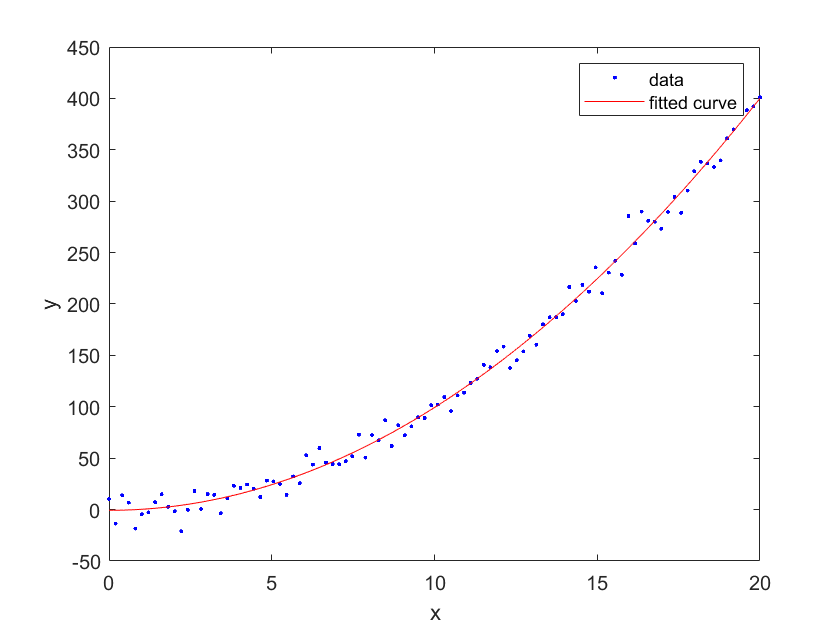

% plot the fitted parameters
figure
plot(quadfit,x,y)

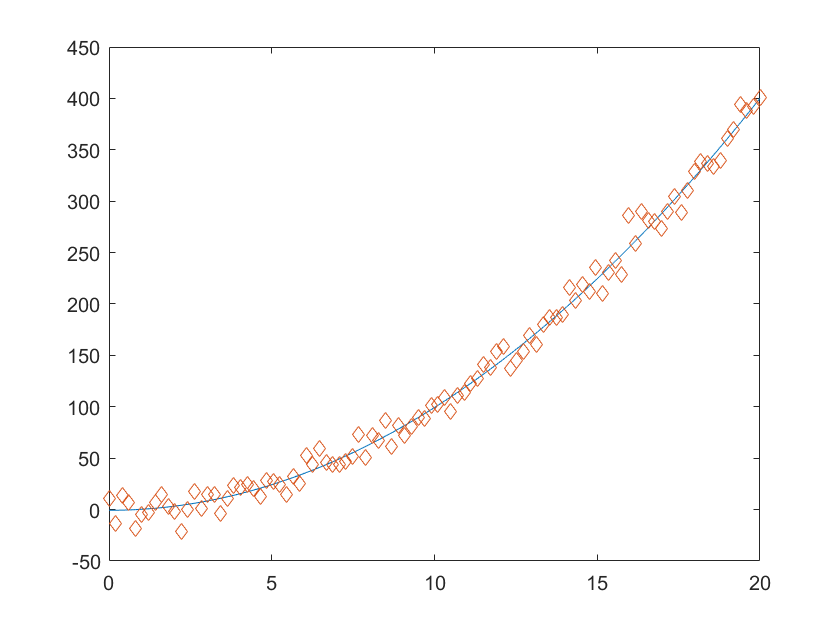

% or
figure
yfit = (quadfit2(1)*(x.^2))+(quadfit2(2)*x)+quadfit2(3);
plot(x,yfit);hold on
scatter(x,y,'Marker','diamond')

## 2.2 Fit Quality

The quality of a fit is very important in regression analysis because it is possible to fit a trendline on a set of data even though the certain line does not represent a real trend. There are certain tools which can be used to observe if the fitted line represents a true trend in the data.

**Confidence Bounds**

The fit object displays the 95% confidence bounds of the parameters after the fitiing model is created showing the boundries where the model is 95% accurate.

Observe the confidence bounds

quadfit = fit(x',y','poly2')

quadfit =      Linear model Poly2:
     quadfit(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       1.004  (0.9374, 1.07)
       p2 =    -0.03346  (-1.403, 1.336)
       p3 =     -0.6689  (-6.594, 5.256)

**Residuals**

The residuals are an important tool in  assessing the quality of a fit. The residuals can be visualised when using the fit object to plot by using the name-value pair.

Plot the residuals of the last fit

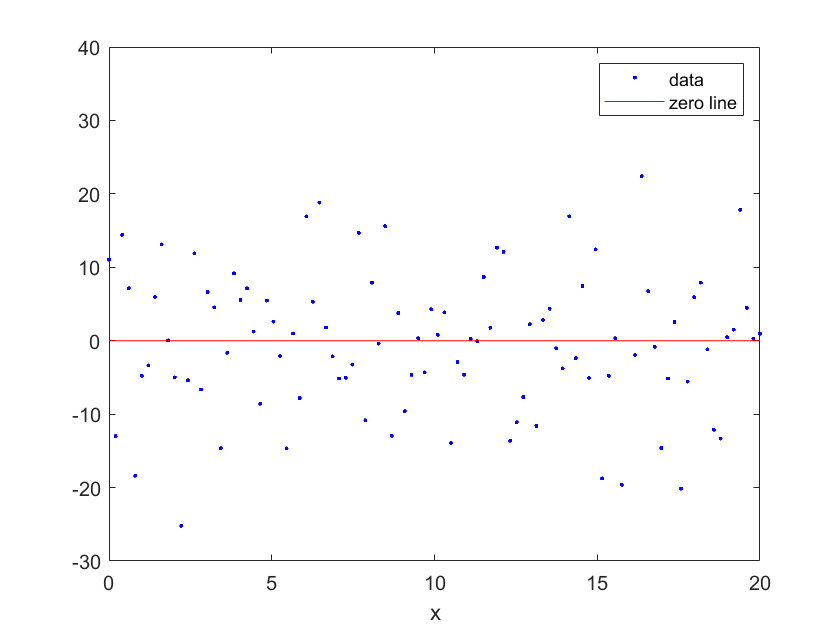

figure
plot(quadfit,x',y','residuals')

The residuas are expected to be randomly distributed around the zero line to ensure for a good fit.

**Fit Quality Indicators**

R-squared is a widely used indicator of the quality of a fit. It is a value between 0 and 1 where a value closer to 1 indicates a better fit. The fit function gives parameters relating to the goodness of fit when an extra output parameter is provided.

Provide an extra output for the fit function and observe the R-square value as well as other fit quality parameters.

[quadfit,gof] = fit(x',y','poly2')

quadfit =      Linear model Poly2:
     quadfit(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       1.004  (0.9374, 1.07)
       p2 =    -0.03346  (-1.403, 1.336)
       p3 =     -0.6689  (-6.594, 5.256)

gof = struct with fields:
           sse: 9.9936e+03
       rsquare: 0.9932
           dfe: 97
    adjrsquare: 0.9931
          rmse: 10.1502


r_square=gof.rsquare 

r_square = 0.9932

## 2.3 Non-Linear Regression

Linear regression can be used to fit non-linear  lines on data in some cases as well. For the fit function some non-linear fitting models are:

- exponential function-exp1

- power function-power1

- sum of power function and constant-power2

- sinusoidal sine function-sin1

- sum of two sine functions-sin2

Challenge: Try using the sin fitting method with the fit function

# 3. Data Interpolation

Interpolation methods allow you to create new data points between known data points. A distinction is made between **linear interpolation**, where an interpolant is formed by fitting a staight line between known data points, and **nonlinear interpolation**, which creates an interpolant by fitting a more or less curved line between data points, or by using indexing.

## 3.1 Linear Interpolation

Linear interpolation is typically used to estimate missing values between known data points. We can linearly interpolate by fitting straight lines between adjacent data points. Each interpolated point will be exactly on the line segment connecting consecutive points. 

**3.1.1 Fill in missing data**

In this section we will fill the missing values in the dataset using the linear interpolation method.

% Create a dataset of monthly mean values of temperature for one year 

months= [1:2,4:9,11:12] % the numeric month of the year with two missing values 

months =      1     2     4     5     6     7     8     9    11    12


Temp= [sort(randi(30,5,1),'descend');sort(randi(30,5,1),'ascend')] % the mean temperature for months vector

Temp =     25
    20
    15
    14
     9
     2
     5
     8
    10
    18


t=datetime(2017,months,1) % create datetime values for vector 'months' to pick out the month labels in 

t = 1×10 datetime array
   01-Jan-2017   01-Feb-2017   01-Apr-2017   01-May-2017   01-Jun-2017   01-Jul-2017   01-Aug-2017   01-Sep-2017   01-Nov-2017   01-Dec-2017


% string format
monthLabels=month(t,'shortname') % 'month' function return the shortname of months in t

monthLabels = 1×10 cell array
    {'Jan'}    {'Feb'}    {'Apr'}    {'May'}    {'Jun'}    {'Jul'}    {'Aug'}    {'Sep'}    {'Nov'}    {'Dec'}


plot(months,Temp,'o-') % visualise the data 

You can see in the plot that there are two missing data points, in March and October.

- Task 1 - Find the interpolated temperature values for March and October using the `'``interp1``'` function.

% Assign the value of the missing months to a variable 
March_Oct=[3,10] 

March_Oct =      3    10



% Find interpolated values for this months 
Temp_M_O=interp1(months,Temp,March_Oct)

Temp_M_O =    17.5000    9.0000


- Task 2 - Add the interpolated values to the plot

% Add the next plot to the current plot
hold on

% Plot the interpolated points 
plot(March_Oct,Temp_M_O,'bo','MarkerFaceColor','b')

**3.1.2 Resample data**

In this section we will create an evently spaced linear interpolation of the original data.

clear all; close all; clc

% Create a dataset of salt concentration in water and the corresponding conductivity of water

concentration= [0,142,610,1170,2035,2297,2665,3264,3565,4349,5148] % salt concentration

concentration =            0         142         610        1170        2035        2297        2665        3264        3565        4349        5148


conductivity=[42,592,1040,1605,2170,2756,3137,4030,4341,4878,5115] % conductivity of water 

conductivity =           42         592        1040        1605        2170        2756        3137        4030        4341        4878        5115


plot(concentration,conductivity,'-*') % visualise the data

As you can see in the plot the concentration values are not at even increments. Therefore, we can resample the concentration data by creating a vector of evently spaced values.

- Task 3 - Create a vector of 11 evently spaced values between 0 and 5000 using the `'``linspace``'` function

Conc_New=linspace(0,5000,11) % vector of x-values for interpolation 

Conc_New =            0         500        1000        1500        2000        2500        3000        3500        4000        4500        5000


- Task 4 - Find the interpolated conductivity values for the new concentration vector 

Cond_New=interp1(concentration,conductivity,Conc_New) % interpolated values 

Cond_New = 	1.0e+03 *

    0.0420    0.9347    1.4335    1.8205    2.1471    2.9662    3.6364    4.2738    4.6390    4.9228    5.0711


- Task 5 - Add the interpolated values to the plot 

% Add the next plot to the current plot
hold on

% Plot the interpolated points 
plot(Conc_New,Cond_New,'bd','MarkerSize',5) % 'MarkerFaceColor','auto'

hold on % to add the next plot into the current plot

The default interpolation method of 'interp1' function is `'``linear``'` (the fourth input to specify the interpolation method). There are five other common options for methods, which belong to nonlinear interpolation methods that will be explained in the next section.

## **3.2 Non-Linear Interpolation**

- Cubic spline `'``spline``' `interpolation uses cubic polynomials and the interpolant is smoth across the whole dataset, by calculating the interpolated value using more than two neighboring points. However, the interpolant can sometimes oscilate widely between data points.

- The `'``pchip``'` method uses also cubic polynomials, but prevents oscillation between data points, as the interpolant is forced to maintain whether the data is increasing or decreasing.

- Using indexing to interpolate instead of polynomials: `'``next``'`(interpolated value same as the next value in the data), `'``previous``'`(interpolated value same as the previous value in the data) and `'``nearest``'`(interpolated value same as the nearest -next or previous- value in the data)

**3.2.1 Resampling data**

We will continue working with the conductivity data. We will find an even sampling of the data and apply different interpolation methods.

- Task 6 - Create a vector of 11 equally spaced points from 0 to 5000 

Conc_New=linspace(0,5000,11)

Conc_New =            0         500        1000        1500        2000        2500        3000        3500        4000        4500        5000


- Task 7 - Find the interpolated conductivity values for the new concentration vector using the `'``spline``'` method

Cond_New_S=interp1(concentration,conductivity,Conc_New, 'spline')

Cond_New_S = 	1.0e+03 *

    0.0420    0.9968    1.4392    1.7247    2.1031    2.9994    3.6180    4.2842    4.6731    4.9484    5.0972


- Task 8 - Add the interpolated values to the plot 

% Plot the interpolated points 
plot(Conc_New,Cond_New_S,'mo','MarkerSize',5)
hold on % to add the next plot into the current plot

- Task 8 - Find the interpolated conductivity values for the new concentration vector using the `'``nearest``'` method. Add the interpolated values to the plot 

Cond_New_N=interp1(concentration,conductivity,Conc_New, 'nearest')

Cond_New_N =           42        1040        1605        1605        2170        3137        4030        4341        4878        4878        5115


plot(Conc_New,Cond_New_N,'k*','MarkerSize',3)


- Task 9 - Add a legend that shows the original and interpolated data

legend('original data', 'linear interp.', 'Spline Interp.', 'Nearest Interp.')

## **3.2.2 Challenge** 

We will continue working with the conductivity data. We will find an even sampling of the data of 100 equally spaced points from 0 to 5000 and compare different interpolation methods.

- Visualise the data set

- Create a vector of 100 equally spaced points from 0 to 5000

- Alppy the linear interpolation method to find missing values for vector created above (see 2.) and visualise the result by addig a plot to the existing plot

- Apply the spline interpolation mothod and visualise the results as in previous point

- Apply the next interpolation method and visualise the results

- Apply a legend to the plot

clear all, close all,clc

concentration= [0,142,610,1170,2035,2297,2665,3264,3565,4349,5148] % salt concentration

concentration =            0         142         610        1170        2035        2297        2665        3264        3565        4349        5148


conductivity=[42,592,1040,1605,2170,2756,3137,4030,4341,4878,5115] % conductivity of water

conductivity =           42         592        1040        1605        2170        2756        3137        4030        4341        4878        5115



% 1. 
plot(concentration,conductivity,'-*') % visualise the data
hold on
% 2.
Conc_New=linspace(0,5000)

Conc_New = 	1.0e+03 *

         0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


% 3.
Cond_New_L=interp1(concentration,conductivity,Conc_New) % Linear Interp.

Cond_New_L = 	1.0e+03 *

    0.0420    0.2376    0.4332    0.6011    0.6495    0.6978    0.7461    0.7945    0.8428    0.8912    0.9395    0.9879    1.0362    1.0870    1.1379    1.1889    1.2398    1.2908    1.3418    1.3927    1.4437    1.4946    1.5456    1.5965    1.6325    1.6655    1.6985    1.7315    1.7645    1.7975    1.8304    1.8634    1.8964    1.9294    1.9624    1.9954    2.0284    2.0614    2.0944    2.1273    2.1603    2.2499    2.3628    2.4758    2.5887    2.7017    2.7832    2.8354    2.8877    2.9400


plot(Conc_New,Cond_New_L,'bd')
hold on
% 4.
Cond_New_S=interp1(concentration,conductivity,Conc_New,'spline') % spline Interp.

Cond_New_S = 	1.0e+03 *

    0.0420    0.2763    0.4665    0.6177    0.7348    0.8228    0.8865    0.9310    0.9612    0.9820    0.9984    1.0154    1.0379    1.0699    1.1112    1.1598    1.2140    1.2720    1.3319    1.3921    1.4506    1.5058    1.5557    1.5987    1.6331    1.6597    1.6800    1.6954    1.7076    1.7178    1.7278    1.7389    1.7528    1.7708    1.7945    1.8254    1.8651    1.9149    1.9765    2.0512    2.1408    2.2460    2.3627    2.4838    2.6019    2.7099    2.8007    2.8730    2.9307    2.9782


plot(Conc_New,Cond_New_S,'mo')
hold on
% 5.
Cond_New_N=interp1(concentration,conductivity,Conc_New,'next') % next Interp.

Cond_New_N =           42         592         592        1040        1040        1040        1040        1040        1040        1040        1040        1040        1040        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2756        2756        2756        2756        2756        3137        3137        3137        3137


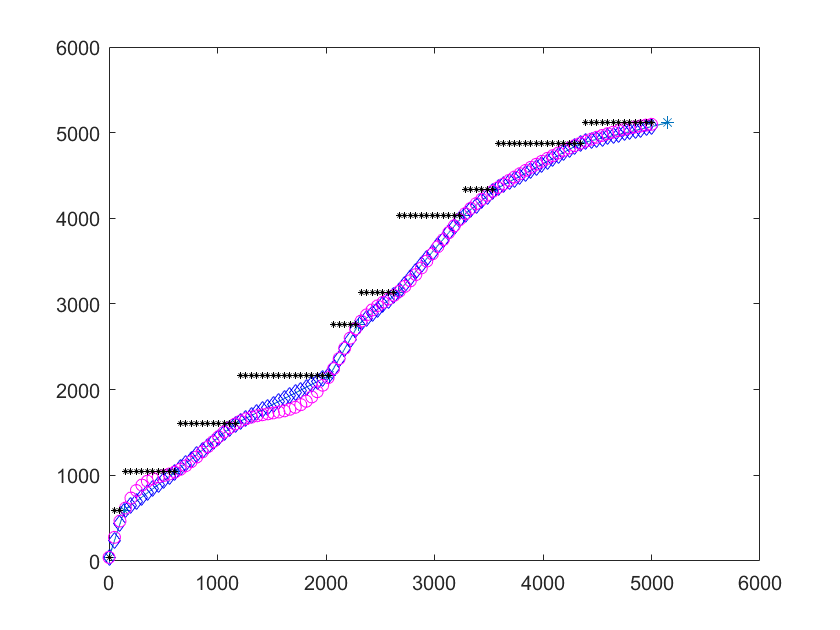

plot(Conc_New,Cond_New_N,'k*','MarkerSize',3)
hold on

# Other Common Statistical Analysis Examples